# Optimización unidimensional usando búsqueda por fibonacci en MATLAB

**Alumno:** Pablo Ruiz Molina

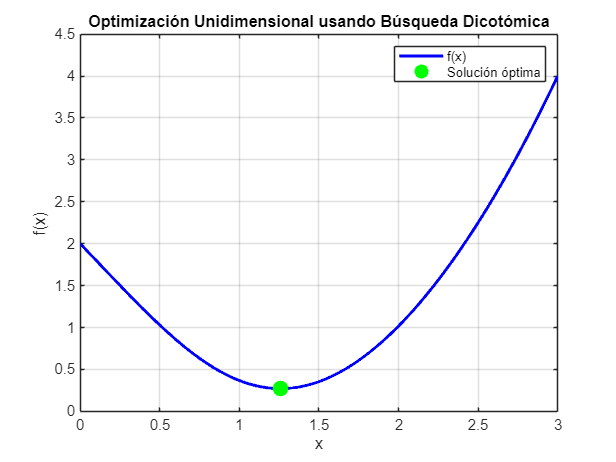

% Limpieza de la consola, variables y figuras
clc; clear; close all;

% Definir la función objetivo
f = @(x) (x-1).^2 + exp(-x.^2);  % Función unimodal

% Definir los límites del intervalo de búsqueda
a = 0;
b = 3;

% Parámetros de la búsqueda dicotómica
delta = 1e-6;  % Tolerancia (delta)

% Inicialización de las variables
%max_iter = 100;  % Número máximo de iteraciones

% Obtener la solución óptima final
[f_opt, x_opt, iter] = fibo(f, a, b, delta);


% Graficar la función objetivo
x_vals = linspace(a, b, 1000);
y_vals = f(x_vals);

figure;
plot(x_vals, y_vals, 'b-', 'LineWidth', 2);
legend('f(x)');
hold on;
% Marcar la solución óptima en el gráfico
plot(x_opt, f_opt, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', 'Solución óptima');
xlabel('x');
ylabel('f(x)');
title('Optimización Unidimensional usando Búsqueda Dicotómica');
grid on;
hold off;

% Mostrar los resultados
disp('Punto óptimo (x):');

Punto óptimo (x):


disp(x_opt);

    1.2583



disp('Valor óptimo de f(x):');

Valor óptimo de f(x):


disp(f_opt);

    0.2720



## Anexo

function [f_opt, x_opt, iter] = fibo(f, a, b, delta)
    % Método de búsqueda con fibonacci
    % Entradas:
    %   f: función objetivo
    %   a, b: extremos iniciales del intervalo unimodal
    %   delta: tolerancia para la convergencia
    %
    % Salidas:
    %   f_opt: valor de la función dónde se alcanza el óptimo  
    %   x_opt: punto donde se alcanza el óptimo
    %   iter: número de iteraciones realizadas

    % Paso 1: calcular la sucesión de Fibonacci hasta que F(n) > (b -
    % a)/delta
    fi = [1, 1];
    w1 = b - a;
    n = 2;
    while w1 >= delta*fi(n)
        fi(n + 1) = fi(n) + fi(n-1);
        n = n + 1;
    end
    iter = n - 2;

    % Paso 2: calcular intervalo
    w1 = w1/fi(n)*fi(n-1);
    xa = b - w1;
    xb = a + w1;

    % Paso 3: evaluación inicial de la función en los puntos xa y xb
    fa = f(xa);
    fb = f(xb);

    % Paso 4: Para k = 2 hasta n - 2 hacer
    k = 2; 
    while (k <= n-2) && (xa < xb) %La segunda condición es para evitar errores en caso de muchas iteraciones
        k = k + 1;

        % Paso 5: actualizar el intervalo y reevaluamos
        w1 = w1/fi(n-k+1)*fi(n-k);
        if fa > fb 
            a = xa;
            xa = xb;
            fa = fb;
            xb = a + w1;
            fb = f(xb);
        else
            b = xb;
            xb = xa;
            fb = fa;
            xa = b - w1;
            fa = f(xa);
        end
        
    end
    % Paso 6: Cálculo del mínimo
    x_opt = (a + b)/2;
    f_opt = f(x_opt);

end